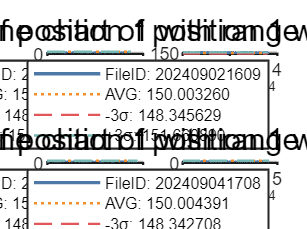

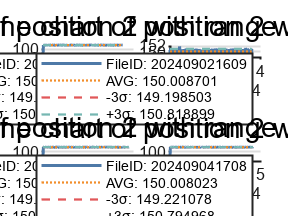

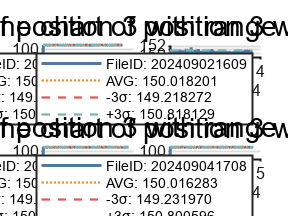

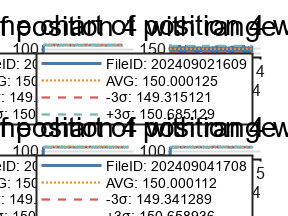

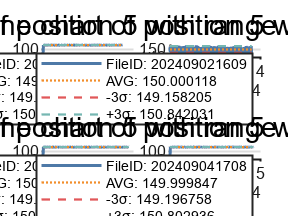

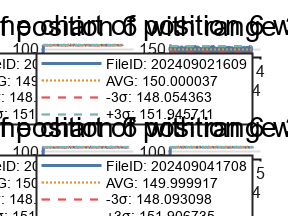

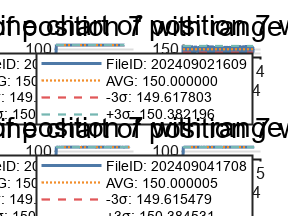

% Clear the workspace
clear;
% Load data
run("ProgramFile\TemperatureAnalysis\LoadData_MethodTwo_HotPlate.m");
run("ProgramFile\TemperatureAnalysis\LoadData_MethodTwo_Wafer.m")
% Load color set
run("ProgramFile\ColorSet\Color.m"); 

% Define the enum type to choose the way to draw line charts.
hp_way_to_draw = enum_way_to_draw.DRAW_BY_DATE ;
wafer_way_to_draw = enum_way_to_draw_wafer.DRAW_WITH_ONE_FILE_IN_3D; % DRAW_OFF;

% Define the enum type to decide whether to fit the normal distribution.
way_to_fit = enum_fit_norm_status.FIT_NORM_OFF ;


% -------------------- Draw the line charts with hot plate data --------------------

% ========== Draw a basic line charts on same figure different axis ==========
if hp_way_to_draw == enum_way_to_draw.DRAW_BY_DATE
    close all;
    clc;
    for i = 1:1:7
        figure;
        for j = 1:1:HP_FILES_NUM
            % According to the number of files determine the layout.
            if (HP_FILES_NUM <4)
                subplot(1, HP_FILES_NUM, j);
            else
                subplot(2, ceil(HP_FILES_NUM/2), j);
            end
            plot(hp_xaxiscell{j}, table2array(hp_datacell{1, j}(:, i)), ...
                "DisplayName", sprintf("FileID: %s",hp_namestr{j}), ...
                "LineWidth", 1.5);
            hold on;
            plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i), height(hp_datacell{1, j}), 1), ...
                "DisplayName", sprintf("AVG: %.6f", hp_statisticaldata{j}(1, i)), ...
                "LineWidth", 1.1, ...
                "LineStyle", ":");
            hold on;
            plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i) - 3 * hp_statisticaldata{j}(2, i), height(hp_datacell{1, j}), 1), ...
                "DisplayName", sprintf("-3σ: %.6f", hp_statisticaldata{j}(1, i) - 3 * hp_statisticaldata{j}(2, i)), ...
                "LineWidth", 1.1, ...
                "LineStyle", "--");
            hold on;
            plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i) + 3 * hp_statisticaldata{j}(2, i), height(hp_datacell{1, j}), 1), ...
                "DisplayName", sprintf("+3σ: %.6f", hp_statisticaldata{j}(1, i) + 3 * hp_statisticaldata{j}(2, i)), ...
                "LineWidth", 1.1, ...
                "LineStyle", "--");
            title(sprintf("Temperature line chart of position %d with range %.2f - Hot Plate", i, 6 * hp_statisticaldata{j}(2, i)),'FontSize',14)
            set(gca,'Box','off', ...                                
                'LineWidth',1, ...                                  
                'XGrid','off','YGrid','on', ...                     
                'TickDir','out','TickLength',[0.01 0.01], ...       
                'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
            legend;
            colororder(color1002);
            hold off;
        end
    end
end

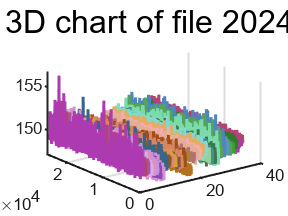

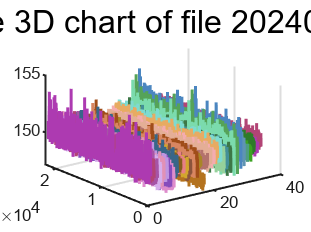

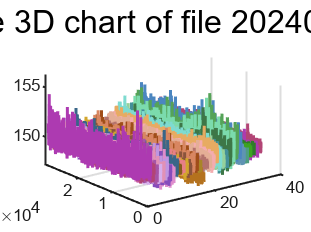

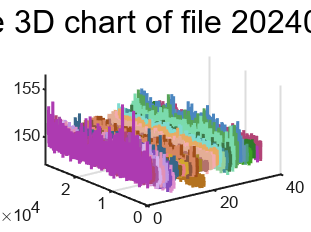


% ========== Just draw line charts with single file ==========
if hp_way_to_draw == enum_way_to_draw.DRAW_WITH_ONE_FILE
    close all;
    clc;
    for j = 1:1:HP_FILES_NUM
        if hp_namestr{j} == "202408301709"
            for i = 1:1:7
                figure;
                plot(hp_xaxiscell{j}, table2array(hp_datacell{1, j}(:, i)), ...
                    "DisplayName", sprintf("FileID: %s",hp_namestr{j}), ...
                    "LineWidth", 1.5);
                hold on;
                plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i), height(hp_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("AVG: %.6f", hp_statisticaldata{j}(1, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", ":");
                hold on;
                plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i) - 3 * hp_statisticaldata{j}(2, i), height(hp_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("-3σ: %.6f", hp_statisticaldata{j}(1, i) - 3 * hp_statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                hold on;
                plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i) + 3 * hp_statisticaldata{j}(2, i), height(hp_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("+3σ: %.6f", hp_statisticaldata{j}(1, i) + 3 * hp_statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                title(sprintf("Temperature line chart on position %d of file %s - Hot Plate", i, hp_namestr{j}),'FontSize',16);
                set(gca,'Box','off', ...                                
                    'LineWidth',1, ...                                  
                    'XGrid','off','YGrid','on', ...                     
                    'TickDir','out','TickLength',[0.01 0.01], ...       
                    'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
                legend;
                colororder(color1006);
                hold off;
            end
        end
    end
end

% ========== Draw a basic line charts on same figure same axis ==========
if hp_way_to_draw == enum_way_to_draw.DRAW_BY_DATE_ON_ONEFIGURE
    close all;
    clc;
    for i = 1:1:7
        figure;
        for j = 1:1:HP_FILES_NUM
            % According to the number of files determine the layout.
            plot(hp_xaxiscell{j}, table2array(hp_datacell{1, j}(:, i)), ...
                "DisplayName", sprintf("FileID: %s",hp_namestr{j}), ...
                "LineWidth", 1.5);
            hold on;
            plot(hp_xaxiscell{j}, repmat(hp_statisticaldata{j}(1, i), height(hp_datacell{1, j}), 1), ...
                "DisplayName", sprintf("AVG: %.6f", hp_statisticaldata{j}(1, i)), ...
                "LineWidth", 1.1, ...
                "LineStyle", ":");
            hold on;
            set(gca,'Box','off', ...                                
                'LineWidth',1, ...                                  
                'XGrid','off','YGrid','on', ...                     
                'TickDir','out','TickLength',[0.01 0.01], ...       
                'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
            legend;
            colororder(color1002);
        end
        hold off;
    end
end

% -------------------- Draw the line charts with wafer data --------------------

% ========== Just draw line charts with single file ==========
if wafer_way_to_draw == enum_way_to_draw_wafer.DRAW_WITH_ONE_FILE
    close all;
    clc;
    for j = 1:1:WF_FILES_NUM
        if wf_namestr{j} == "202408301709"
            for i = 1:1:34
                figure;
                plot(wf_xaxiscell{j}, table2array(wf_datacell{1, j}(:, i)), ...
                    "DisplayName", sprintf("FileID: %s",wf_namestr{j}), ...
                    "LineWidth", 1.5);
                hold on;
                plot(wf_xaxiscell{j}, repmat(wf_statisticaldata{j}(1, i), height(wf_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("AVG: %.6f", wf_statisticaldata{j}(1, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", ":");
                hold on;
                plot(wf_xaxiscell{j}, repmat(wf_statisticaldata{j}(1, i) - 3 * wf_statisticaldata{j}(2, i), height(wf_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("-3σ: %.6f", wf_statisticaldata{j}(1, i) - 3 * wf_statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                hold on;
                plot(wf_xaxiscell{j}, repmat(wf_statisticaldata{j}(1, i) + 3 * wf_statisticaldata{j}(2, i), height(wf_datacell{1, j}), 1), ...
                    "DisplayName", sprintf("+3σ: %.6f", wf_statisticaldata{j}(1, i) + 3 * wf_statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                title(sprintf("Temperature line 3D chart of file %s - Wafer", wf_namestr{j}),'FontSize',16);
                set(gca,'Box','off', ...                                
                    'LineWidth',1, ...                                  
                    'XGrid','off','YGrid','on', ...                     
                    'TickDir','out','TickLength',[0.01 0.01], ...       
                    'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
                legend;
                colororder(color1006);
                hold off;
            end
        end
    end
end

% ========== Draw a 3D line charts with single file ==========
if wafer_way_to_draw == enum_way_to_draw_wafer.DRAW_WITH_ONE_FILE_IN_3D
    for j = 1:1:WF_FILES_NUM
%         if wf_namestr{j} == "202408301709"
            figure;
            for i = 1:1:34
                plot3(i*ones(length(wf_ssxaxiscell{j}), 1), wf_ssxaxiscell{j}, table2array(wf_ssdatacell{1, j}(:, i)), ...
                    "LineWidth", 1.5);
%                     "DisplayName", sprintf("FileID: %s",wf_namestr{j}), ...
                hold on;
            end
            title(sprintf("Temperature line 3D chart of file %s - Wafer", wf_namestr{j}),'FontSize',16);
            set(gca,'Box','off', ...                                
                'LineWidth',1, ...                                  
                'XGrid','off','YGrid','on', ...                     
                'TickDir','out','TickLength',[0.01 0.01], ...       
                'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
%             legend;
            colororder(color1005);
            hold off;
%         end
    end
end





% ------------------------------ Fit the normal distribution ------------------------------
if way_to_fit == enum_fit_norm_status.FIT_NORM_ON
    for j = 1:1:HP_FILES_NUM
        if hp_namestr{j} == "202408301709"
            for i = 1:1:7
                figure;
                normdata = table2array(hp_ssdatacell{1, j}(:, i));
                subplot(1, 2, 1);
                normplot(normdata);
                [normdata_mu, normdata_sigma] = normfit(normdata);
                norm_x = linspace(min(normdata), max(normdata), 100);
                norm_fitted = normpdf(norm_x, normdata_mu, normdata_sigma);
                subplot(1, 2, 2);
                histogram(normdata, 30, 'Normalization', 'pdf');
                hold on;
                plot(norm_x, norm_fitted, 'LineWidth', 1.5);
                colororder(color1002);
                hold off;
            end
        end
    end
end
